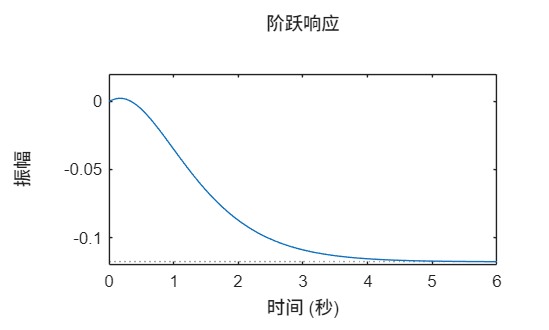

mdl = 'pendulum';
open_system(mdl);
io(1) = linio(strcat(mdl, '/Constant'),1, 'openinput');
io(2) = linio(strcat(mdl, '/plant_model'),1, 'openoutput');
linsys = linearize(mdl,io, 'StateOrder', {'x', 'v', 'theta', 'omega'});
p = [-80, -2.5, -2, -1.5];
K = place(linsys.A , linsys.B, p);
Kc = linsys.A - linsys.B * K;
step(ss(Kc, linsys.B, linsys.C, linsys.D));

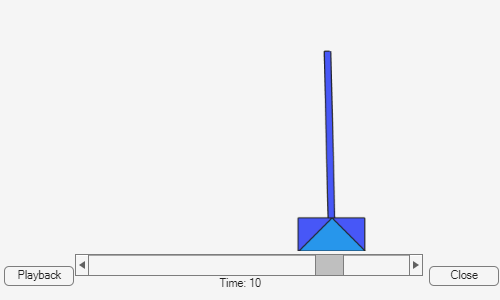

Kf = -1 / (linsys.C * (Kc \ linsys.B));
L = place(linsys.A', linsys.C', p)';
sim(mdl);